% Read table 
clear
tic

% T = readtable("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");
% save ('tradingData.mat', 'T')
load 'tradingData.mat'

% writetable (T, 'dowPortfolio.xlsx') ;
TT = table2timetable (T);
pricesTT = TT(:,2:end) ;
head (pricesTT)

ans = 8×664 timetable
       Time        ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN     AISA     AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF     ADHI     ADES     ACST     ACES    ABMM     ABDA     ABBA    AALI     AMAG     ALTO     ALMI    ALKA     ALDO     AKSI    AKRA    AKPI     AKKU     DLTA     DKFT 


% Create Signal
smaWindSz = 20 ;
smaSignal = movavg (pricesTT, 'linear', smaWindSz) ;

SignalTT = pricesTT ;
SignalTT.Variables = pricesTT.Variables > smaSignal.Variables ;
% SignalTT

SignalTT = 2859×664 timetable
       Time        ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI    AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    DKFT    D

% Initial weights
warmUpPeriod = 20;

equalWeightInitial = [] ;

% Create strategy

rebalFreq = 1 ;
lookback = [40 126] ;
TransactionCosts = 0.0/100 ;

equalWeightStrategy = backtestStrategy ("Equal Weighted", ...
    @equalWeightFcn, "RebalanceFrequency", rebalFreq, "LookbackWindow", 2, ...
    "TransactionCosts",TransactionCosts,"InitialWeights", equalWeightInitial) ;

% Define backtesting engine

AnnualRiskfreeRate = 0/100 ;
backtester = backtestEngine (equalWeightStrategy, "RiskFreeRate", AnnualRiskfreeRate)

backtester =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% Run backtest
backtester = runBacktest (backtester, pricesTT, 'Start', warmUpPeriod)

backtester =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
                NumAssets: 664
                  Returns: [2858×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [2858×1 timetable]
                  BuyCost: [2858×1 timetable]
                 SellCost: [2858×1 timetable]


% Examine backtest results
summaryBacktest = summary (backtester)

summaryBacktest = 9×1 table
                       Equal_Weighted
                       ______________

    TotalReturn              3.7809  
    SharpeRatio             0.11917  
    Volatility            0.0046885  
    AverageTurnover       0.0067728  
    MaxTurnover            0.027699  
    AverageReturn        0.00055863  
    MaxDrawdown             0.28583  
    AverageBuyCost                0  
    AverageSellCost               0  


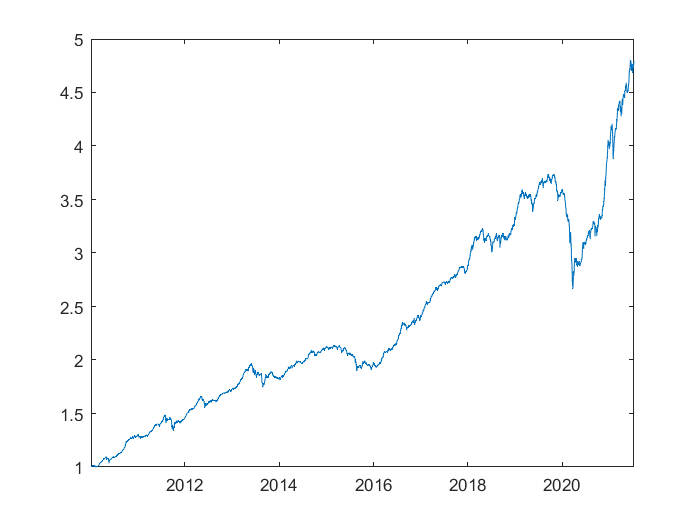

PortfolioPositions = backtester.Positions.Equal_Weighted;
dailyRet = backtester.Returns ;       
cumRet = ret2tick (dailyRet);
plot (cumRet.Time , cumRet.Variables)   

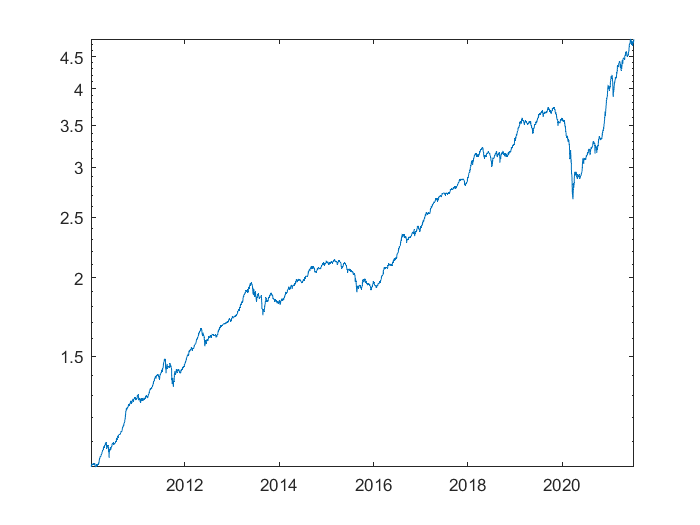

semilogy (cumRet.Time , cumRet.Variables)    

cumRetEnd = cumRet (end, :)

cumRetEnd = 1×1 timetable
       Time        Equal_Weighted
    ___________    ______________

    09-Jul-2021        4.7809    


TimeDate = cumRet.Time ;
CAGR = (cumRetEnd.Variables)^(1/yearfrac(TimeDate(1), TimeDate(end)))-1

CAGR = 0.1455

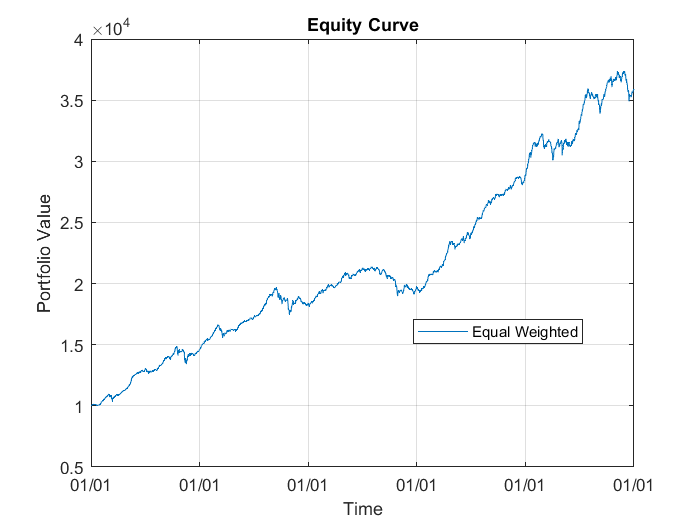

equityCurve (backtester)


toc

Elapsed time is 27.092075 seconds.


Local Functions

function new_weights = equalWeightFcn(current_weights, pricesTT, SignalTT)
% Equal-weighted portfolio allocation

nAssets = size(pricesTT.Variables, 2);
Signal = SignalTT.Variables ;
nInvestableAssets = sum(Signal (end,:),2) ;
new_weights = ones(1,nAssets) .* Signal (end,:);
new_weights = new_weights / nInvestableAssets ;

end